% read wav files
[audio_1,rate_1]=audioread("./src/myaudio/audio1.wav");
[audio_2,rate_2]=audioread("./src/myaudio/audio2.wav");
[audio_3,rate_3]=audioread("./src/myaudio/audio3.wav");
[audio_4,rate_4]=audioread("./src/myaudio/audio4.wav");

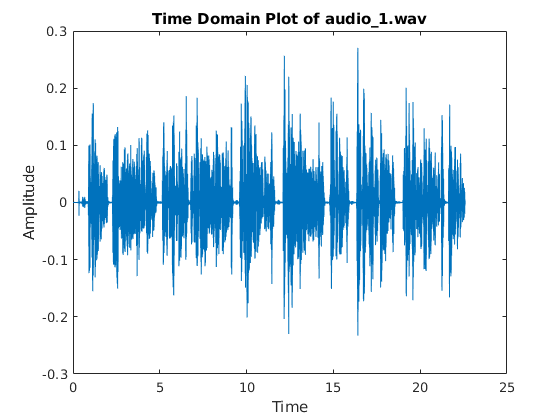

% time domain
% audio_1.wav
audio_vec=audio_1(:,1);
dt=1/rate_1;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_1.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_1.png');

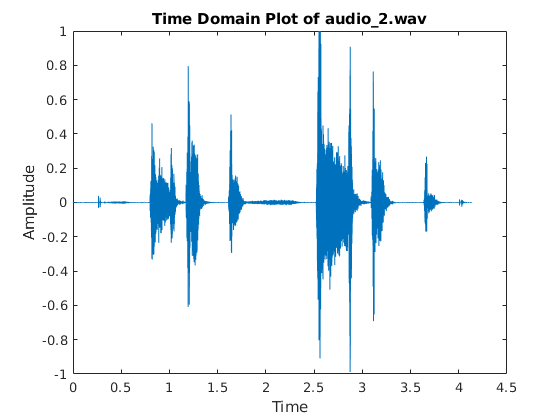

% audio_2.wav
audio_vec=audio_2(:,1);
dt=1/rate_2;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_2.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_2.png');

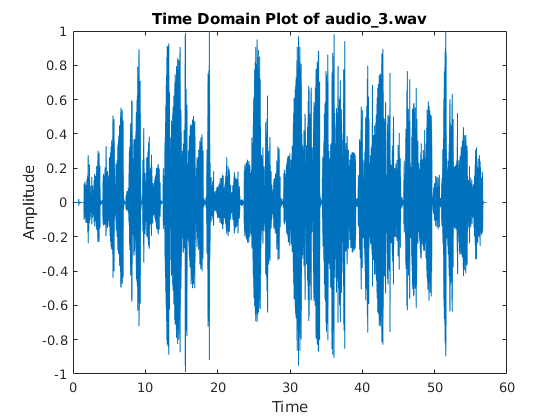

% audio_3.wav
audio_vec=audio_3(:,1);
dt=1/rate_3;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_3.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_3.png');

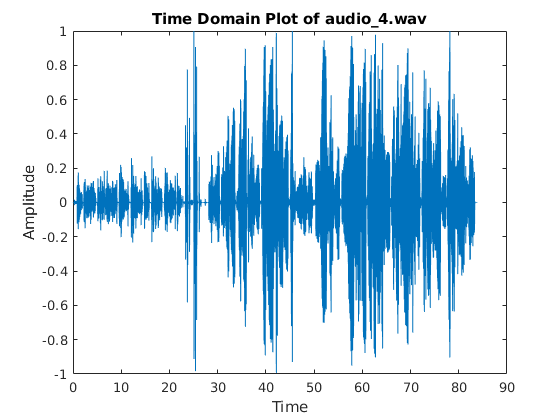

% audio_4.wav
audio_vec=audio_4(:,1);
dt=1/rate_4;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_4.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_4.png');

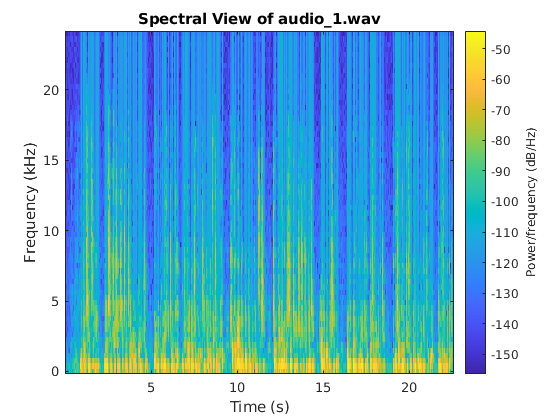

% spectral view
% audio_1.wav
audio_vec=audio_1(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_1,'yaxis');
title("Spectral View of audio\_1.wav");
saveas(gcf,'./result/spectral_view/audio_1.png');

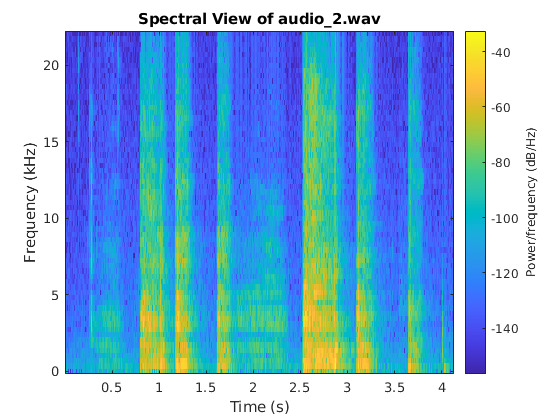

% audio_2.wav
audio_vec=audio_2(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_2,'yaxis');
title("Spectral View of audio\_2.wav");
saveas(gcf,'./result/spectral_view/audio_2.png');

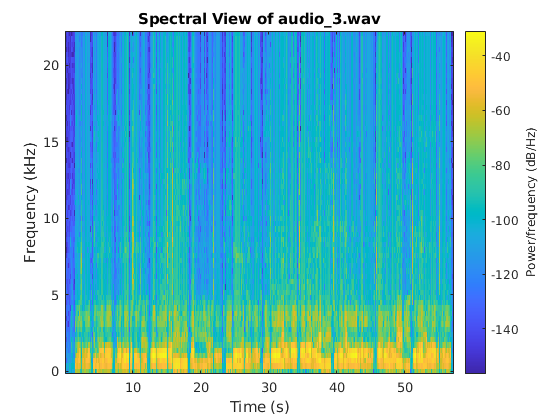

% audio_3.wav
audio_vec=audio_3(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_3,'yaxis');
title("Spectral View of audio\_3.wav");
saveas(gcf,'./result/spectral_view/audio_3.png');

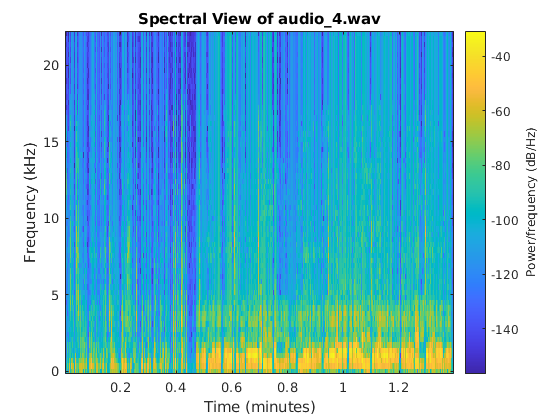

% audio_4.wav
audio_vec=audio_4(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_4,'yaxis');
title("Spectral View of audio\_4.wav");
saveas(gcf,'./result/spectral_view/audio_4.png');

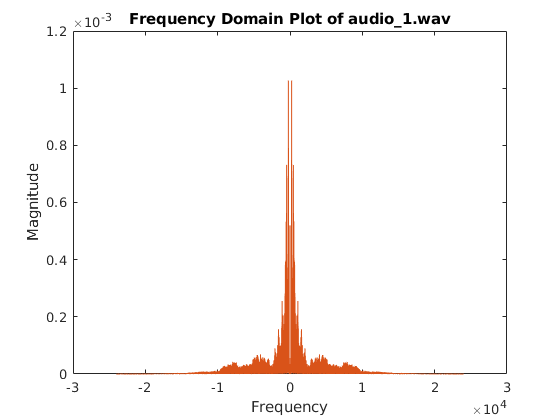

% frequency domain
% audio_1.wav
audio_length=length(audio_1);
df=rate_1/audio_length;
frequency=-rate_1/2:df:rate_1/2-df;
audio_fft=fftshift(fft(audio_1))/length(fft(audio_1));
plot(frequency,abs(audio_fft));
title('Frequency Domain Plot of audio\_1.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_1.png');

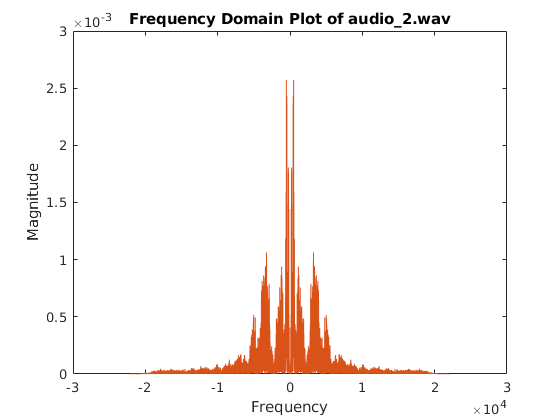

% audio_2.wav
audio_length=length(audio_2);
df=rate_2/audio_length;
frequency=-rate_2/2:df:rate_2/2-df;
audio_fft=fftshift(fft(audio_2))/length(fft(audio_2));
plot(frequency,abs(audio_fft));
title('Frequency Domain Plot of audio\_2.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_2.png');

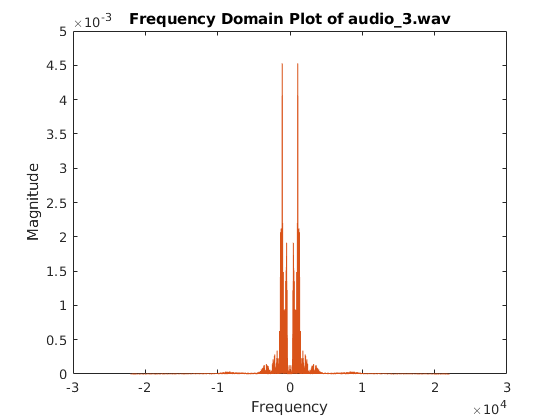

% audio_3.wav
audio_length=length(audio_3);
df=rate_3/audio_length;
frequency=-rate_3/2:df:rate_3/2-df;
audio_fft=fftshift(fft(audio_3))/length(fft(audio_3));
plot(frequency,abs(audio_fft));
title('Frequency Domain Plot of audio\_3.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_3.png');

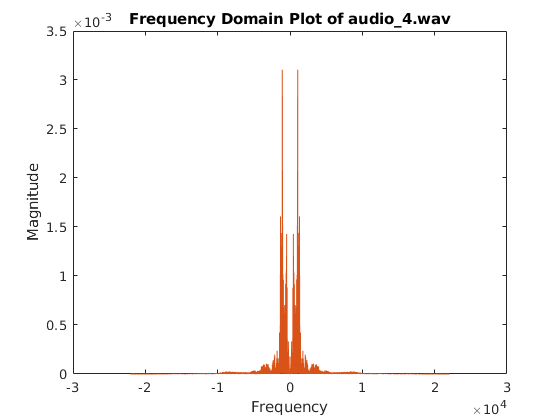

% audio_4.wav
audio_length=length(audio_4);
df=rate_4/audio_length;
frequency=-rate_4/2:df:rate_4/2-df;
audio_fft=fftshift(fft(audio_4))/length(fft(audio_4));
plot(frequency,abs(audio_fft));
title('Frequency Domain Plot of audio\_4.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_4.png');